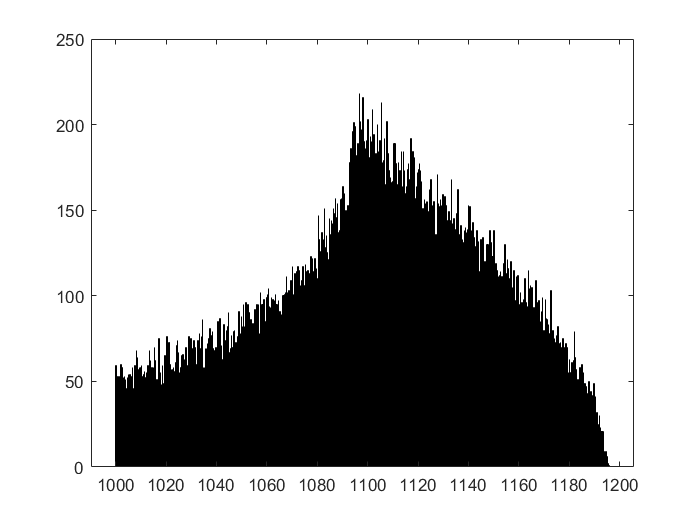

% Lab 5 - Kyle McEleney

% The purpose of this data set is to develop a criteria which will allow
% for detection of the Higgs Boson. The data utilized here is simulated for
% the purposes of developing this discrimination method. 

% The data is to be collected using the ATLAS detector at the LHC facility.
% Generally, large amounts of trials are performed in order to gather a
% collection of data sets which characterize the resultant jet generated
% from the 13 TeV center-of-mass energy collision. The center-of-mass
% energy is the energy available for new particle generation due to the
% collision.

% The ATLAS detector itself has many subsystems of detectors used to detect mass, energy, momentum, lifetime, charges, and nuclear spins.
% It is designed to have the widest possible range of detection in order to
% sense both the expected range, and those which may be unexpected.

% The main method of investigation in this study are the fundamental characteristics of the
% resultant jet which are used to reconstruct the collision to determine
% whether or not a Higgs boson was created.

% Descriptions of the different parameters provided for analysis are given
% below.

clear all; close all;

% h5disp("higgs_100000_pt_1000_1200.h5")
mydata1 = h5read("higgs_100000_pt_1000_1200.h5","/higgs_100000_pt_1000_1200");
mydata2 = h5read("qcd_100000_pt_1000_1200.h5","/qcd_100000_pt_1000_1200");


% The momentum is detected using the effects of the large magnetic field
% designed to bend the paths of the particles generated.

higgs_momentum = mydata1(1,:);
qcd_momentum = mydata2(1,:);

% histogram of higgs momentum measurement values
histogram(higgs_momentum,1000);

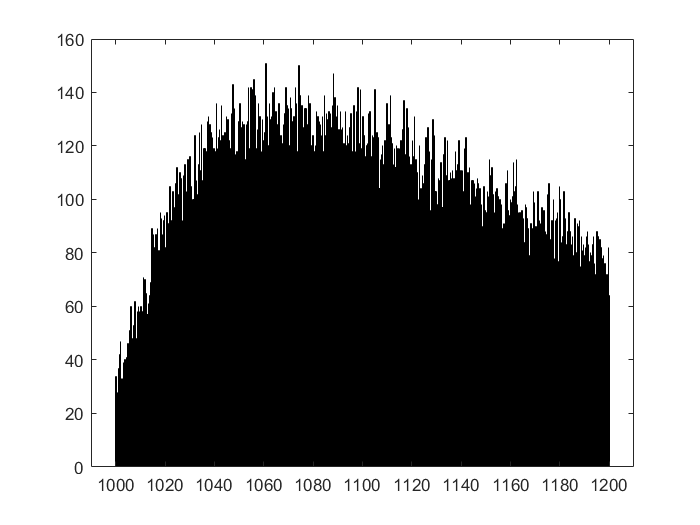

% This histogram illustrates the distribution of the Higgs Boson momentum
% measurements. The majority of momenta fall below a value of 1180. 5 sigma determinations may be made on the high side of the distribution.
% The prominent spike at 1100 suggests the presence of a feature of interest.

% histogram of qcd (background) momentum measurement values
histogram(qcd_momentum,1000);

% Histogram illustrating the distribution of QCD measurements which vary
% between values of 1000 and 1200. It resembles a Gaussian distribution
% with a high sigma value. This makes sense since this is meant to be the
% background distribution.

% Pseudorapidity - Defined as the spatial coordinate describing the angle
% of a jet relative to the beam axis.


$$\eta =-\mathrm{ln}\left(\mathrm{tan}\left(\frac{\Theta }{2}\right)\right)-\frac{1}{2}\mathrm{ln}\left(\frac{\left|P\right|+P_2 }{\left|P\right|-P_2 }\right)$$


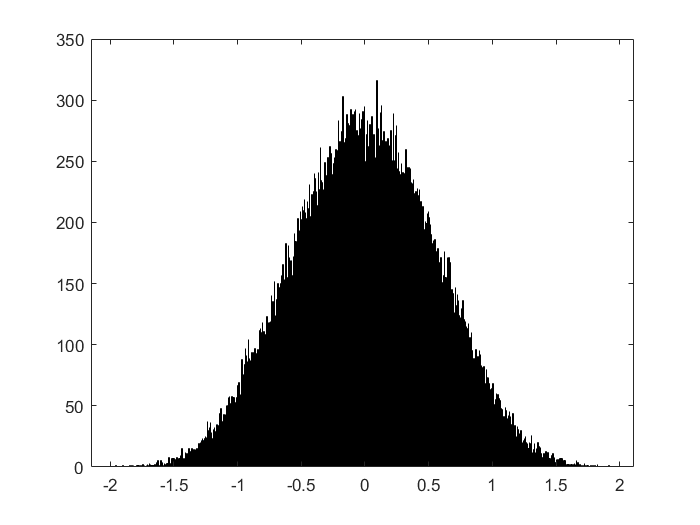

% Where theta is the angle between the jet and the particle beam, 
% P2 is the component of the three momentum of the jet along the particle beam axis, 
% and P is the three momentum of the jet.

% This quantity is sensed by one of the two calorimeters installed in the
% detector. Which calorimeter detects the particle depends on the scale and
% charge of the particles.

higgs_pseudo = mydata1(2,:);
qcd_pseudo = mydata2(2,:);


histogram(higgs_pseudo,1000);

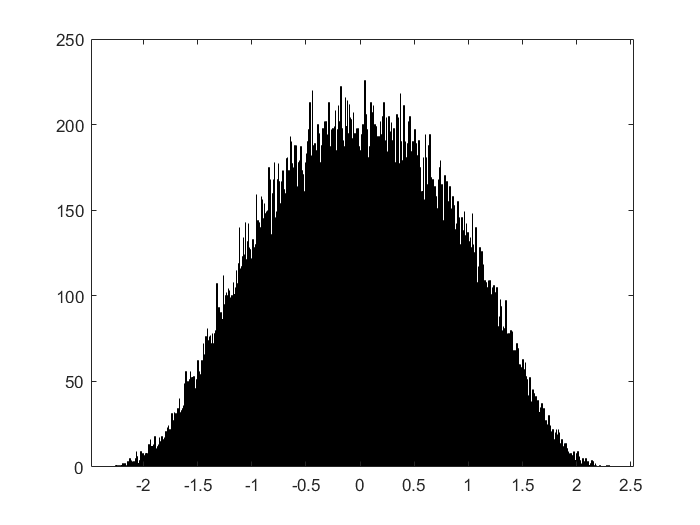

% This histogram represents the signal data. By comparison to the following
% histogram, there are no significant points which are outliers from the
% background data set. 

histogram(qcd_pseudo,1000);

% The Higgs pseudorapidity data set is more closely
% centered about zero which corresponds to a deflection angle of 90 degrees
% from the beam's path. These are the deflections events of interest as they
% suggest the collision of the two particles of interest yielding a
% dramatic change in trajectory.


% Distributions of the azimuthal angles of the jets produced by the
% collisions in radians.


$$\phi ={\mathrm{cos}}^{-1} \left(\frac{x}{r}\right)$$


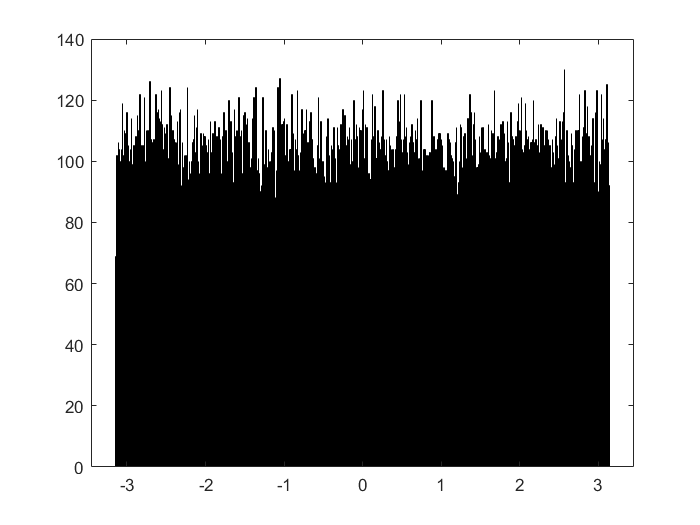

% These angles are determined by the data generated by the calorimeters as
% particles pass through generating collisions with gasses which liberate
% electrons. This generates an analog signal which can be used to
% determine which particle was present based off of a particle's expected
% charge in this scenario.

higgs_azimuthal = mydata1(3,:);
qcd_azimuthal = mydata2(3,:);


histogram(higgs_azimuthal,1000);

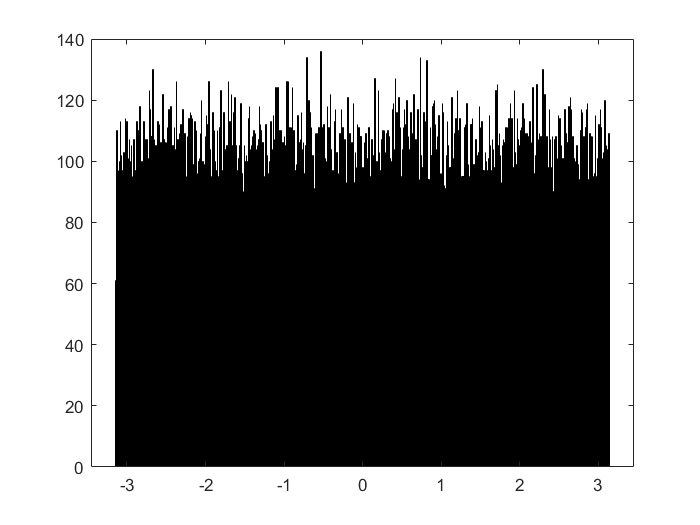

% At a glance, there is no notable pattern in the signal data set. A random
% distribution is expected from -3.14 to +3.14 as there shouldn't be any
% tendencies of the particles to deflect at a specific angle.

histogram(qcd_azimuthal,1000);

% There is no significant signal present when both types of data sets are
% compared. Both vary throughout the entire range of azimuthal angles.


% Mass of jets produced by the collision. Defined as the invariant mass of
% the jet. Derived from the following equation for the invariant mass of a
% system:


$$E^2 =m^{2\;} +p^2$$


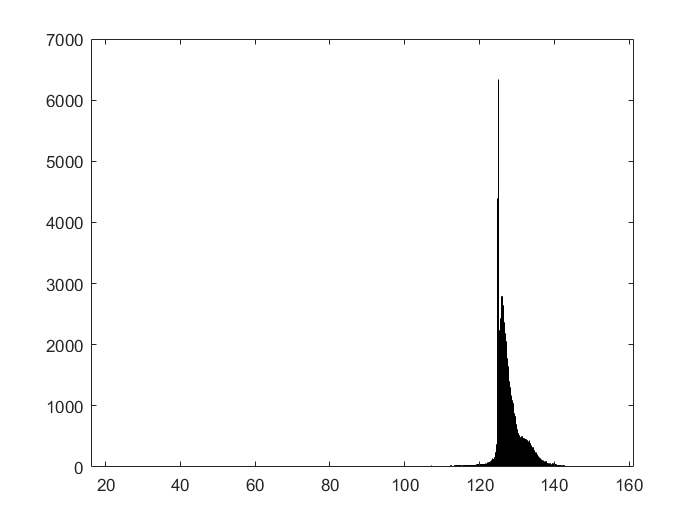

higgs_mass = mydata1(4,:);
qcd_mass = mydata2(4,:);

histogram(higgs_mass,1000);

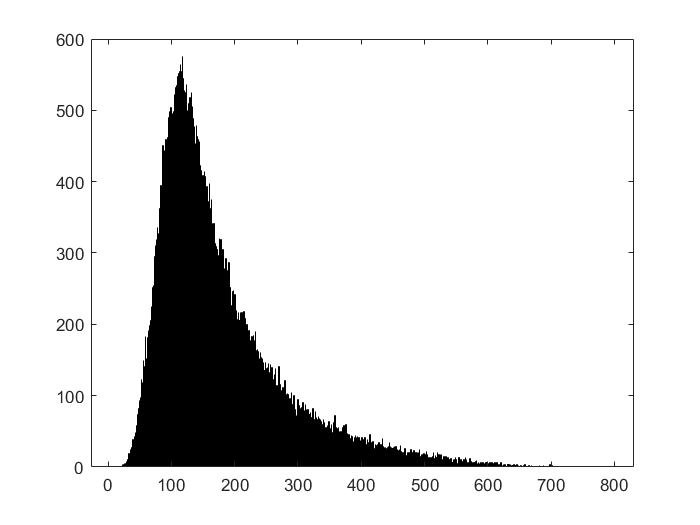

% The sharp peak shown somewhere around 125 suggests that the collision of
% interest produces jets of a specific mass. The range of this distribution
% is quite small when compared to the wide distribution found in the
% background dataset below. The narrow band of masses of interest suggests
% that this may be a primary criterion used to filter large data sets down
% to those of interest, allowing for smaller processing times of the
% remaining data.

histogram(qcd_mass,1000);

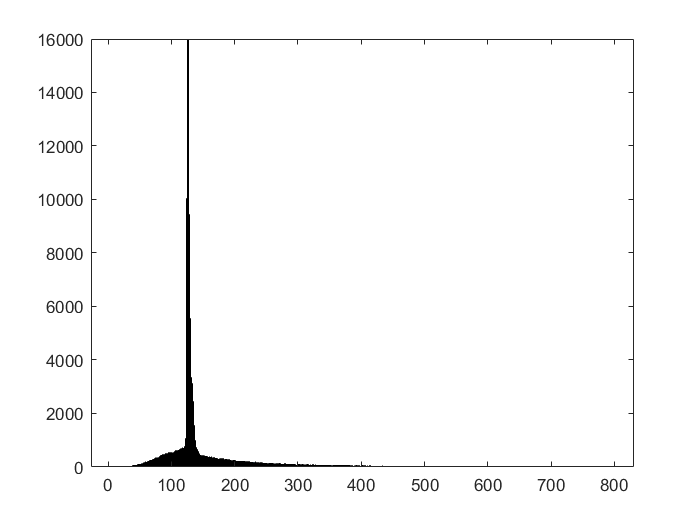

% The two data sets exhibit two pronounced differences in Poisson
% Distributions. The first which is meant to exhibit signal-like
% characteristics has a sharp peak in counts (lambda) at ~126. The second
% shows a typical Poisson distribution with a lambda of ~110.

% The combination of the two data sets is shown below to illustrate the
% difference in features between the styles of the data sets.

total_mass = [qcd_mass, higgs_mass];
histogram(total_mass,1000);

% 2 Point Energy Correlation Function (ECF) ratio

% For both the 2 and 3 point ECF measurements, resonances of the jets were
% explored in order to determine their constituency. 2 point correlator
% functions are generally used for discriminating quarks and gluons.

% This method is based on the energies and pair-wise angles of particles within a jet, 
% and does not require that subregions of the jet be explicitly identified for use.


$$e_2 =\sum_{i<j\in J} p_{T,i} P_{T,j} \Delta R_{i,j} \frac{1}{P_{T,J}^2 }$$


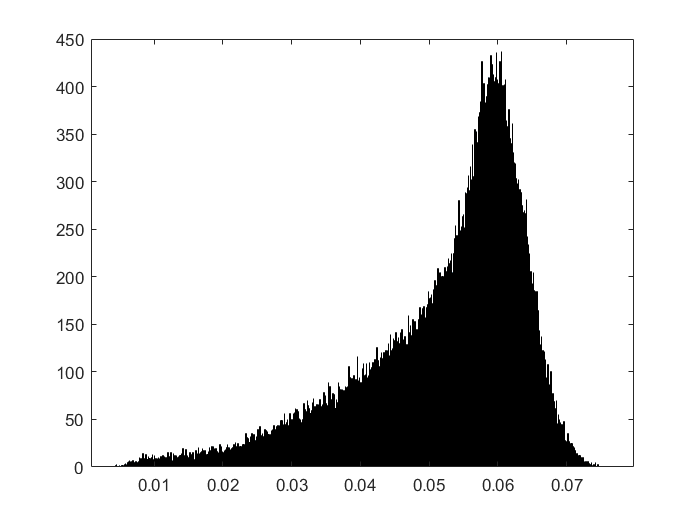

higgs_ecf_2 = mydata1(5,:);
qcd_ecf_2 = mydata2(5,:);
histogram(higgs_ecf_2,1000);

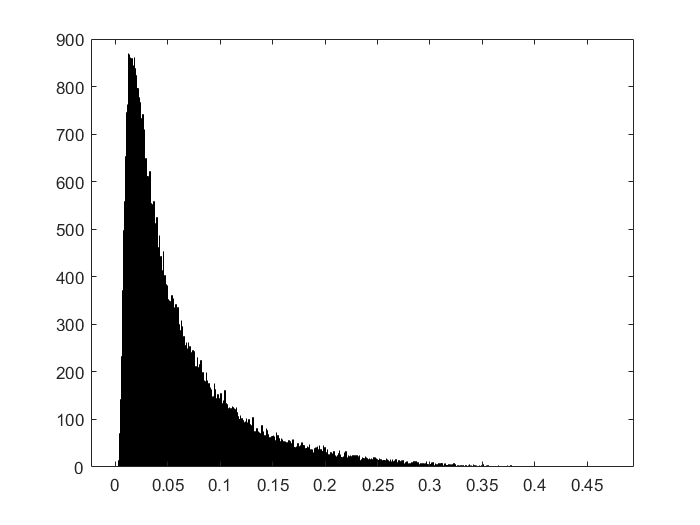

histogram(qcd_ecf_2,1000);

% The significant difference in profiles between the signal and background
% data suggest that this may be another suitable candidate to filter that
% data set with. However, this is less rigid than the mass as there is
% significant overlap in ranges. Anything greater than ~0.07 can be taken to be a background reading. 

% 3 point Energy Correlation Function (ECF) ratio

% This discrimination method is generally used to discriminate boosted W/Z/Higgs
% Bosons. It is based on the energies and pair-wise angles of particles within a jet, 
% and does not require that subregions of the jet be explicitly identified for use.   


$$e_3 =\sum_{i<j<k\in J} P_{T,i} P_{T,j} P_{T,k} {\Delta R}_{\mathrm{ij}} {\Delta R}_{\mathrm{ik}} {\Delta R}_{\mathrm{jk}} \frac{1}{P_{T,J}^3 }$$


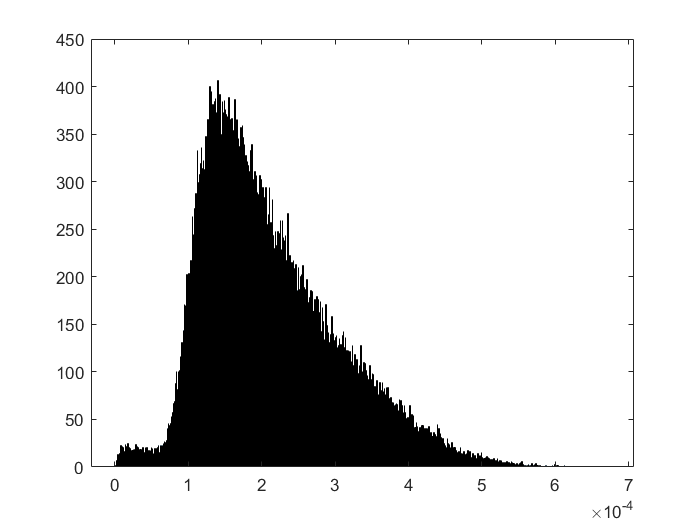

higgs_ecf_3 = mydata1(6,:);
qcd_ecf_3 = mydata2(6,:);
histogram(higgs_ecf_3,1000);

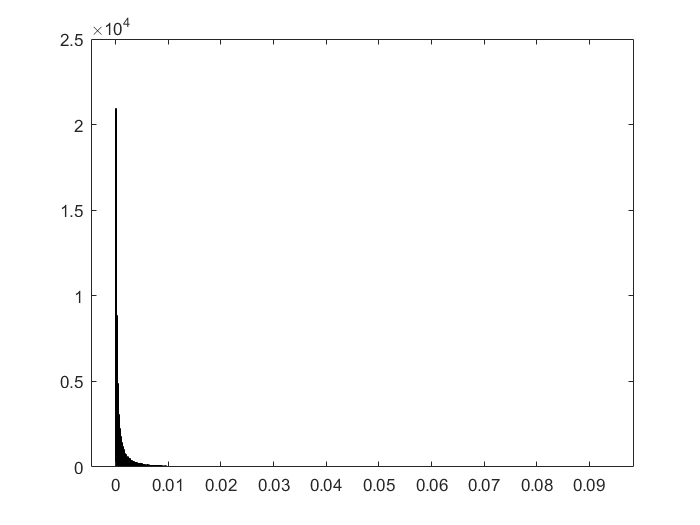

histogram(qcd_ecf_3,1000);

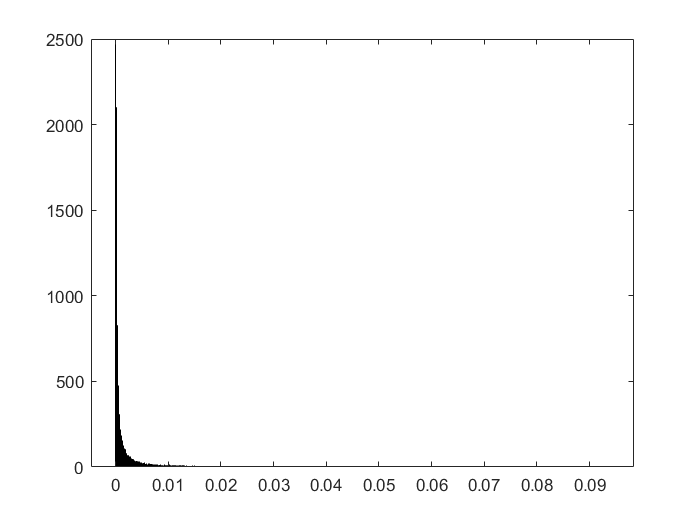

histogram(qcd_ecf_3,10000);

%xlim([0,0.001])

% 3 to 2 point ECF ratio


$$D_2 =\frac{e_3 }{e_2^3 }$$


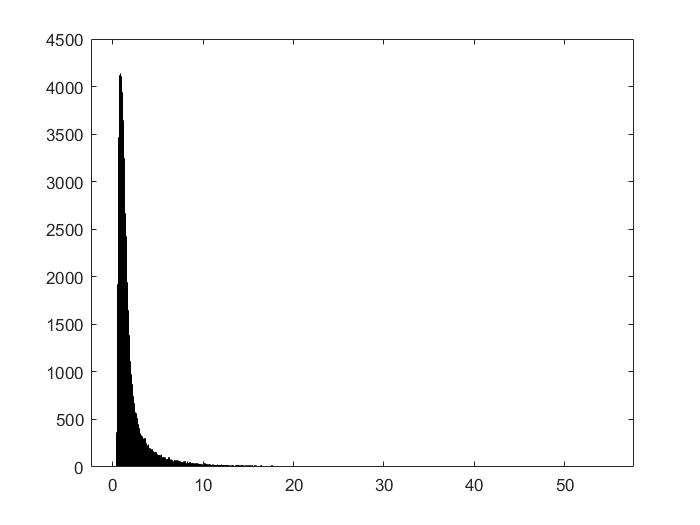

higgs_ecf_ratio = mydata1(7,:);
qcd_ecf_ratio = mydata2(7,:);
histogram(higgs_ecf_ratio,1000);

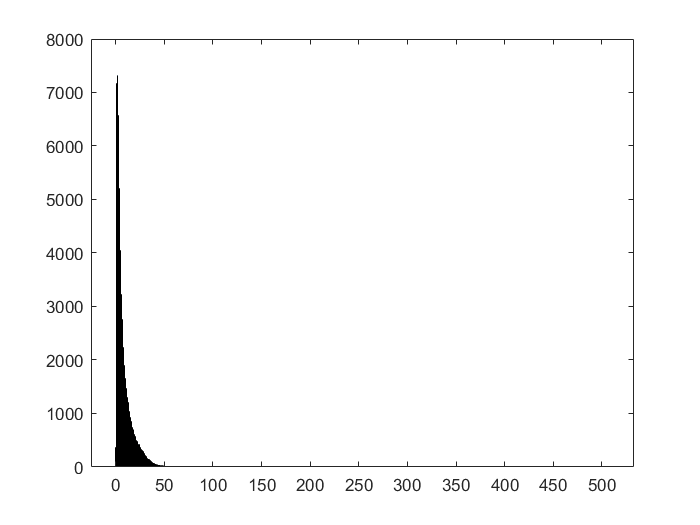

histogram(qcd_ecf_ratio,1000);

% Angularity


$$\tau_{-2} =\frac{1}{m_j }\sum_{i\in J} E_i \left({\mathrm{sin}}^{-2} \left(\Theta_i \right)\right)\left({\mathrm{cos}}^3 \left(\Theta_i \right)\right)$$


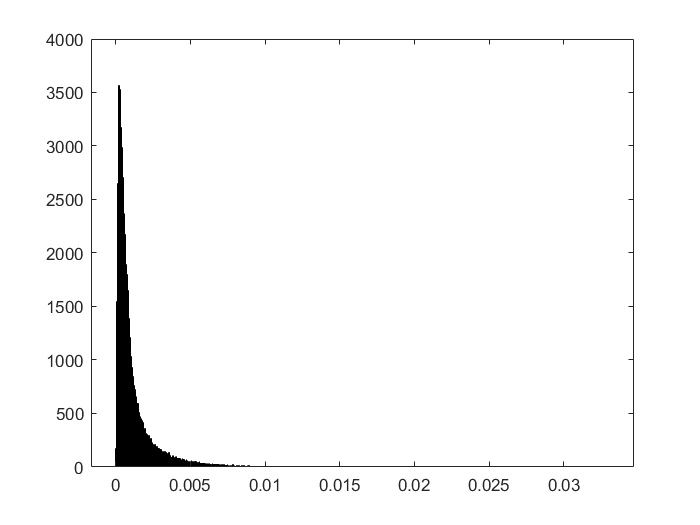

higgs_angularity = mydata1(8,:);
qcd_angularity = mydata2(8,:);
histogram(higgs_angularity,1000);

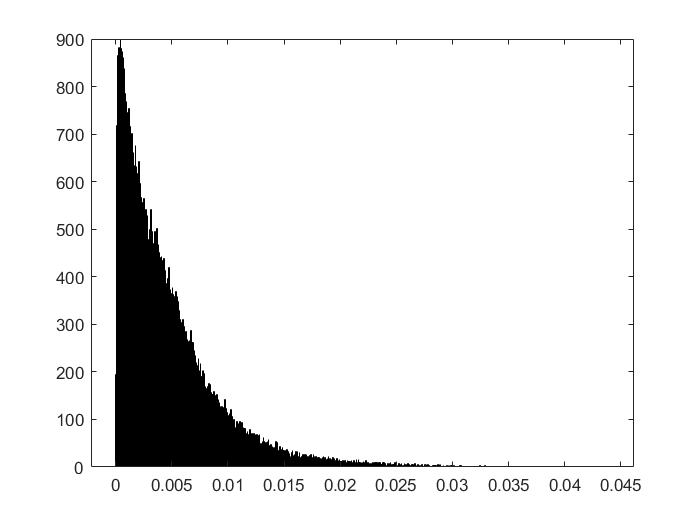

histogram(qcd_angularity,1000);

%1 - The main features which provide strong discrimination power between the
% background and the signal data sets are the following: Jet mass, and 3-point ECF ratio. 

% To a lesser extent, the following may be used but would require greater levels of analysis to properly utilize:
% Tranverse momentum, Pseudorapidity, 2-point ECF ratio, and 3-to-2 point ECF ratio. 
% These sets would be better used as second or third order criteria since they
% have substantial overlap between the signal and background data. However,
% distributions may be generated which allow for thresholds to be generated
% below the 5 sigma benchmark. 

% The azimuthal angle of the jet and the angularity have poor
% discrimination potential as they have nearly identical profiles between
% the signal and background data.

%2 Feature correlations.
% Broadly speaking, the features which have the greatest discrimination
% power should have obvious correlations in regards to whether or not a
% signal is present. The jet mass has the strongest
% discrimination characteristics which should be used to determine
% correlation features. The transverse momentum is directly correlated to
% the mass since p = mv.

% Another strong correlation has to do with the 2 point ECF, 3 point ECF, and 3 to
% 2 ratio. These values are largely determined using the associated masses
% of particles of interest.

%3 Compute expected discovery sensitivity by normalizing each sample
% appropriately.

%4 Develop a plan to optimize the discovery sensitivity by applying
% selections to these features.
% In order to narrow down the data set, the entries should be narrowed down
% utilizing the different characteristics of the distribution profiles. For
% example, the differences in pseudorapidity profile's sigma values allow
% for an associated sigma value to be determined over which data points
% will be included. This method becomes easier when considering the mass
% where there are significant amounts of counts within a small range.

% Once the thresholds within the data have been determined (and associated
% acceptable sigma values), a discrimination profile may be produced to
% hone in on specific data sets which are likely to yield illuminating data
% points. 
